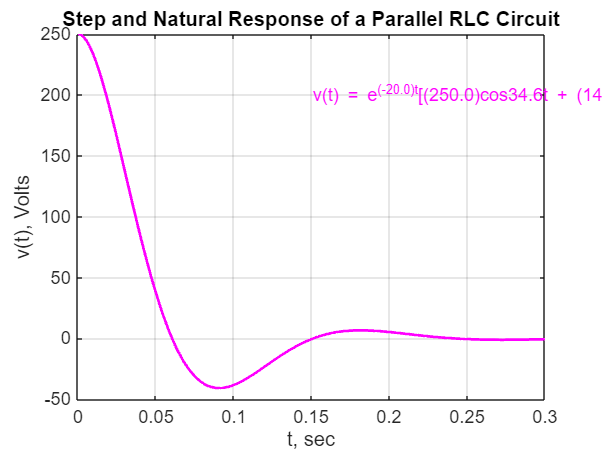

v(t) = e^{(-20.0)t}[(250.0)cos34.6t + (144.6)sin34.6t]


% Input parameters
R = 500; % Resistance in ohms

L = 2.5 ; % Inductance in H
C = 50 * 1e-6; % Capacitance in F
Is = 4; % Current source in A
I0 = 0; % Initial inductor current in A
V0 = 250; % Initial capacitor voltage in V

% Time vector
t = linspace(0, 0.3, 1000); % Time range (0 to 0.3 seconds)

% Calculating constants
alpha = 1 / (2 * R * C); % Damping factor
omega_0 = 1 / sqrt(L * C); % Natural frequency
omega_d = sqrt(omega_0^2 - alpha^2); % Damped angular frequency

% Coefficients A and B based on initial conditions
A = V0; % Voltage initial condition
B = (I0 / C + alpha * V0) / omega_d; % Current initial condition

% Voltage across the circuit
v_t = exp(-alpha * t) .* (A * cos(omega_d * t) + B * sin(omega_d * t));

% Current through inductor
iL_t = C * [diff(v_t) / (t(2) - t(1)), 0]; % Numerical derivative of v(t)

% Current through capacitor
iC_t = diff([v_t, v_t(end)]) / (t(2) - t(1)); % Numerical derivative of v(t)

% Current through resistor
iR_t = v_t / R;

% User selects the output
disp('Select the output to plot:');
disp('1. Voltage across the circuit (v_t)');
disp('2. Current through inductor (iL_t)');
disp('3. Current through capacitor (iC_t)');
disp('4. Current through resistor (iR_t)');

output_choice = input('Enter the number of your choice: ');

% Plot based on user selection
figure;
switch output_choice
    case 1
        plot(t, v_t, 'm', 'LineWidth', 1.5);
        title('Voltage across RLC Circuit');
        ylabel('Voltage (V)');
        equation = sprintf('v(t) = e^{-%.2ft} [%.2f\\cos(%.2ft) + %.2f\\sin(%.2ft)]', ...
            alpha, A, omega_d, B, omega_d);
    case 2
        plot(t, iL_t, 'b', 'LineWidth', 1.5);
        title('Current through Inductor (i_L)');
        ylabel('Current (A)');
        equation = 'i_L(t) = C \frac{dv(t)}{dt}';
    case 3
        plot(t, iC_t, 'r', 'LineWidth', 1.5);
        title('Current through Capacitor (i_C)');
        ylabel('Current (A)');
        equation = 'i_C(t) = \frac{dv(t)}{dt}';
    case 4
        plot(t, iR_t, 'g', 'LineWidth', 1.5);
        title('Current through Resistor (i_R)');
        ylabel('Current (A)');
        equation = 'i_R(t) = \frac{v(t)}{R}';
    otherwise
        disp('Invalid choice. Please run the script again.');
        return;
end
xlabel('Time (s)');
grid on;

% Add the equation to the plot
text(0.02, max(v_t) * 0.9, ['Equation: ', equation], 'FontSize', 10, 'Color', 'k', 'BackgroundColor', 'w');
